# การวิเคราะห์เชิงความถี่

# ตอนที่ 9 : ความกว้างแถบความถี่ของระบบพลวัต (Bandwidth of Dynamical System)

ตราบใดที่ระบบพลวัตเป็น LTI เราสามารถที่จะทำการวิเคราะห์เชิงความถี่ ไม่ว่าจะเป็นระบบทางกายภาพจเป็นระบบไฟฟ้า ระบบเครื่องกล หรือระบบอื่นๆ

## ตัวอย่างที่ 1

กำหนดให้ระบบทางกลแบบหมุนเป็นดังแผนภาพวงจรดังกล่าว

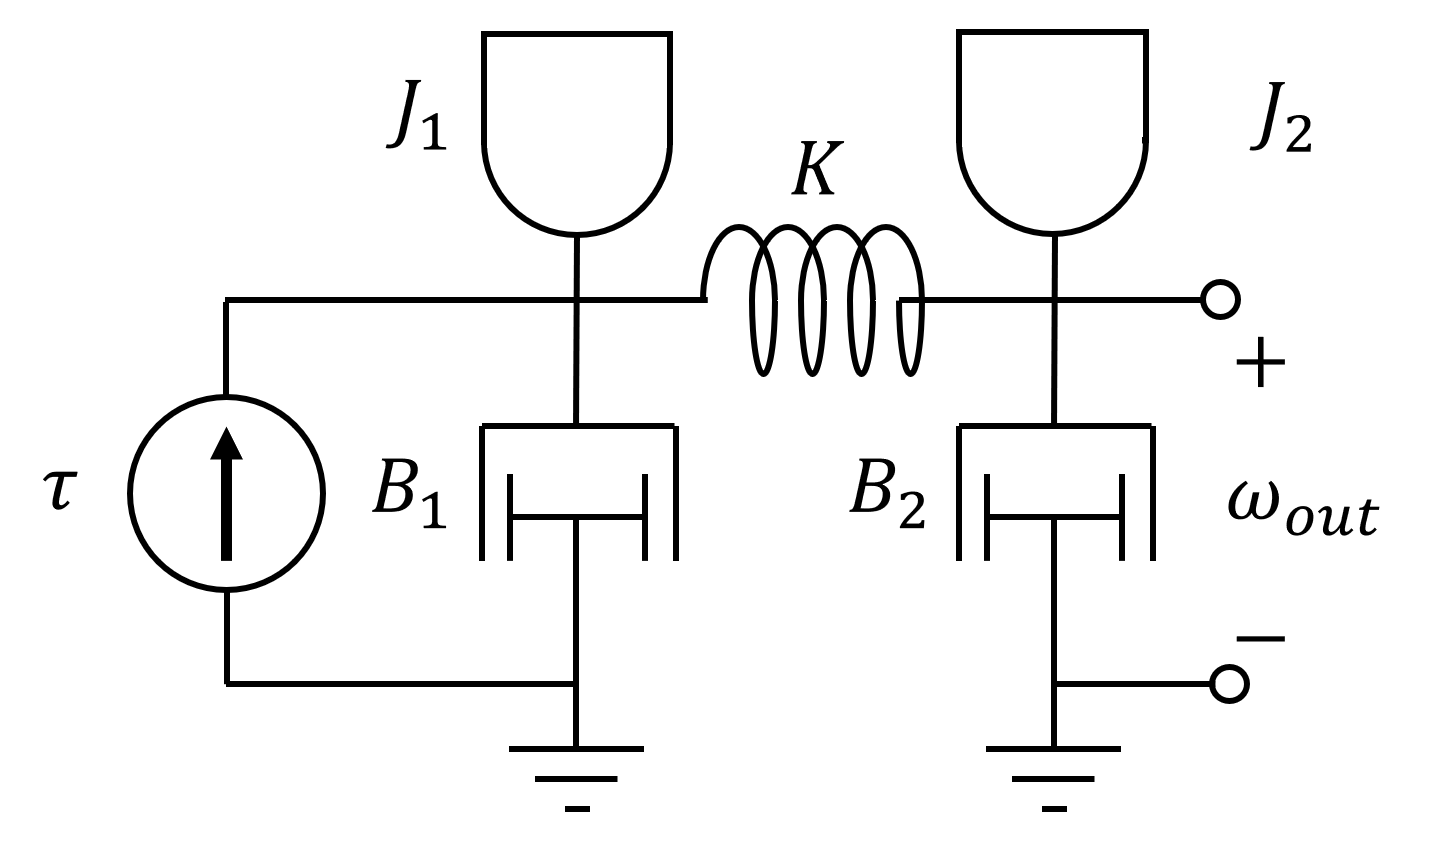

โดยที่ 

$\tau$ คือแรงบิดอินพุตที่กระทำกับเพลาที่หนึ่ง

$\omega_{\textrm{out}}$ คือความเร็วเชิงมุมของเพลาที่สองที่มีเซนเซอร์วัดความเร็วติดอยู๋ (ชื่อตัวแปรคล้ายกับตัวแปรอิสระ $\omega$ แต่มีความหมายคนละแบบ)

$J_1$ คือความเฉื่อยของเพลาที่หนึ่ง

$J_2$ คือความเฉื่อยของเพลาที่สอง

$B_1$ คือสัมประสิทธิ์ความฝืดเชิงมุมของตลับปืนที่ทำกับเพลาที่หนึ่ง

$B_2$ คือสัมประสิทธิ์ความฝืดเชิงมุมของตลับปืนที่ทำกับเพลาที่สอง

$K$ คือค่าคงที่ของสปริงเชิงมุมระหว่างเพลาที่หนึ่งและเพลาที่สอง

เราสามารถหาสมการเชิงอนุพันธ์ได้ดังต่อไปนี้


$$\begin{array}{l}
J_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(\omega_1 \right)=\tau -B_1 \omega_1 +\tau_s \\
J_2 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(\omega_2 \right)=-\tau_s -B_2 \omega_2 \\
\frac{\mathrm{d}}{\mathrm{d}\;t}\left(\tau_s \right)=K\left(\omega_2 -\omega_1 \right)\\
\omega_{\mathrm{out}} =\omega_2 
\end{array}$$


เราสามารถแก้สมการเชิงอนุพันธ์โดยแปลงเป็นระบบสมการเชิงเส้นในโดเมนของลาปลาซ


$$\begin{array}{l}
J_1 s\;\Omega_1 \left(s\right)=T\left(s\right)-B_1 \Omega_1 \left(s\right)+T_s \left(s\right)\\
J_2 s\;\Omega_2 \left(s\right)=-T_s \left(s\right)-B_2 \Omega_2 \left(s\right)\\
s\;T_s \left(s\right)=K\left(\Omega_2 \left(s\right)-\Omega_1 \left(s\right)\right)
\end{array}$$


เมื่อทำการจัดรูป เราจะได้สมการ


$$\begin{array}{l}
\left(J_1 s+B_1 \right)\Omega_1 \left(s\right)-T_s \left(s\right)=T\left(s\right)\\
\left(J_2 s+B_2 \right)\Omega_2 \left(s\right)+T_s \left(s\right)=0\\
K\Omega_1 \left(s\right)-K\Omega_2 \left(s\right)+s\;T_s \left(s\right)=0
\end{array}$$


จากนั้นเราสามารถเขียนอยู๋ในรูปของสมการเวกเตอร์ได้ดังต่อไปนี้


$$\left\lbrack \begin{array}{ccc}
J_1 s+B_1  & 0 & -1\\
0 & J_2 s+B_2  & 1\\
K & -K & s
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Omega_1 \left(s\right)\\
\Omega_2 \left(s\right)\\
T_s \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack T\left(s\right)$$


เราสามารถคำนวณหาเอ้าท์พุต $\Omega_{\textrm{out}} \left(s\right)$ ได้จากการหา $\Omega_2 \left(s\right)$ ดังนั้น เราจะเขียนสมการความสัมพันธ์ได้ออกมาในรูปดังต่อไปนี้


$$\Omega_{\mathrm{out}} \left(s\right)=\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Omega_1 \left(s\right)\\
\Omega_2 \left(s\right)\\
T_s \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack {\left\lbrack \begin{array}{ccc}
J_1 s+B_1  & 0 & -1\\
0 & J_2 s+B_2  & 1\\
K & -K & s
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack T\left(s\right)$$



$$\begin{array}{l}
G\left(s\right)=\frac{\Omega_{\mathrm{out}} \left(s\right)}{T\left(s\right)}=\frac{K}{\left(J_1 s+B_1 \right)\left(J_2 s^2 +B_2 s+K\right)+\left(J_2 s+B_2 \right)K}\\
G\left(s\right)=\frac{\frac{K}{J_1 }}{s^3 +\left(\frac{B_1 }{J_1 }+\frac{B_2 }{J_2 }\right)s^2 +\left(\frac{K}{J_2 }+\frac{K}{J_1 }+\frac{B_1 }{J_1 }\frac{B_2 }{J_2 }\;\right)s+\left(\frac{B_1 }{J_1 }\frac{K}{J_2 }+\frac{B_2 }{J_2 }\frac{K}{J_1 }\right)}\\
G\left(s\right)=\frac{\kappa_1 }{s^3 +\left(\beta_1 +\beta_2 \right)s^2 +\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)s+\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)}
\end{array}$$


**แปลงอะไรมายังไงวะงง ทำไมตัวกำลังสามกับสองถึงเป็น  s= -jw**


$$\begin{array}{l}
G\left(\omega \right)=\frac{\kappa_1 }{-j\omega^3 -\left(\beta_1 +\beta_2 \right)\omega^2 +j\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega +\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)}\\
G\left(\omega \right)=\frac{\kappa_1 }{\left(\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 \right)+j\left(\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 \right)}\\
G\left(\omega \right)=\frac{\kappa_1 }{\sqrt{{\left(\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 \right)}^2 +{\left(\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 \right)}^2 }{\mathbf{e}}^{j\left(\tan^{-1} \left(\frac{\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 }{\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 }\right)\right)} }\\
G\left(\omega \right)=\frac{\kappa_1 }{\sqrt{{\left(\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 \right)}^2 +{\left(\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 \right)}^2 }}{\mathbf{e}}^{j\left(-\tan^{-1} \left(\frac{\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 }{\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 }\right)\right)} 
\end{array}$$


เราจะได้อัตราส่วนขนาดดังต่อไปนี้


$$\left|G\left(\omega \right)\right|=\frac{\kappa_1 }{\sqrt{{\left(\left(\beta_1 \kappa_2 +\beta_2 \kappa_1 \right)-\left(\beta_1 +\beta_2 \right)\omega^2 \right)}^2 +{\left(\left(\kappa_1 +\kappa_2 +\beta_1 \beta_2 \right)\omega -\omega^3 \right)}^2 }}$$


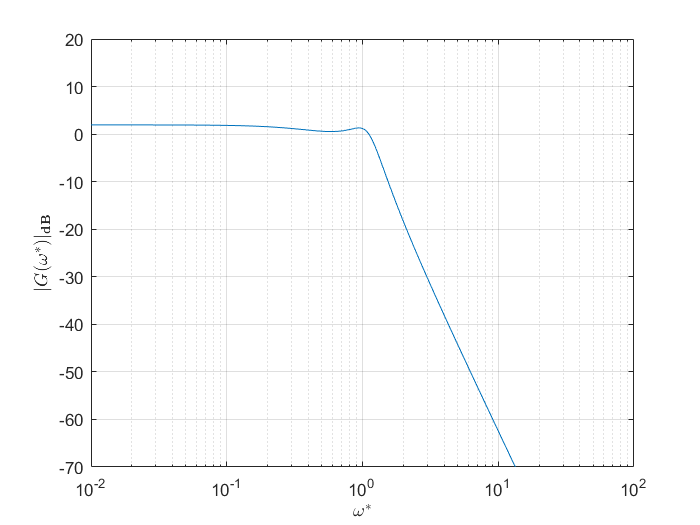

w = 10.^(-2:0.01:2);
J_1 = 0.4; 
J_2 = 1;
B_1 = 0.3;
B_2 = 0.5;
K = 0.3;
kappa_1 = B_1/J_1; 
kappa_2 = B_2/J_2;
beta_1 = K/J_1;
beta_2 = K/J_2;
im = (kappa_1+kappa_2+beta_1*beta_2)*w-w.^3;
re = beta_1*kappa_2+beta_2*kappa_1-(beta_1+beta_2)*w.^2;
mag_G = kappa_1./sqrt(re.^2+im.^2);
pha_G = -atan(im./re);
clf;
ax = axes;
semilogx(ax,w,20*log10(mag_G));
grid(ax,'on');
hold(ax,'on');
DC_gain = kappa_1/(beta_1*kappa_2+beta_2*kappa_1);
% semilogx(ax,w,20*log10(DC_gain*ones(size(w))),'k--');
% semilogx(ax,w,20*log10(DC_gain/sqrt(2)*ones(size(w))),'k--');
axis(ax,[min(w) max(w) -70 20]);
xlabel('$\omega^*$','Interpreter',"latex")
ylabel('$|G(\omega^*)|_\mathbf{dB}$','Interpreter',"latex")

จากกราฟอัตราส่วนขนาดของฟังก์ถ่ายโอนเราจะสังเกตได้ว่าระบบมีพฤติกรรมที่คล้ายกับ ตัวกรอง low-pass แต่ระบบมีการขยายสัญญาณเพิ่มในช่วงที่ความถี่ต่ำเนื่องอัตราส่วนขนาดมีค่ามากกว่า $0\;\textrm{dB}$ ระบบนี้จะตอบสนองดีในหนึ่งแต่จะตอบสนองน้อยกับอีกช่วงหนึ่ง ช่วงที่ระบบตอบสนองได้ดีนั้นคือ ความกว้างแถบความถี่ (bandwidth) ระบบ

**การคำนวณ bandwidth ของระบบมีหลักการคล้ายกับการหาความถี่ตัดโดยเราจะวิเคราะห์หาความถี่ที่ทำให้อัตราส่วนพลังมีค่ามากว่าครึ่งหนึ่งของอัตราส่วนพลัง ณ อินพุตคงที่** หรือเขียนเป็นสมการได้ดังนี้


$$\begin{array}{l}
{\left|G\left(\omega_B \right)\right|}^2 >\frac{1}{2}{\left|G\left(0\right)\right|}^2 \\
\left|G\left(\omega_B \right)\right|>\frac{1}{\sqrt{2}}\left|G\left(0\right)\right|
\end{array}$$


โดย $\omega_B$ คือ bandwidth ของระบบ

**แทนที่เราจะคำนวณจากสมการ เราสามารถประมาณ bandwidth ของระบบได้ด้วยการตีเส้นในกราฟและหาจุดตัดระหว่างกราฟและเส้นนั้น โดนเส้นนี้จะเป็นเส้นที่มีขนาดเท่ากับ **$\frac{1}{\sqrt{2}}$** ของ **$\left|G\left(0\right)\right|$ หรือ 


$$20\log_{10} \left(\frac{1}{\sqrt{2}}\cdot \left|G\left(0\right)\right|\right)={\left|G\left(0\right)\right|}_{\textrm{dB}} -10\log_{10} \left(2\right)\approx {\left|G\left(0\right)\right|}_{\textrm{dB}} -3$$


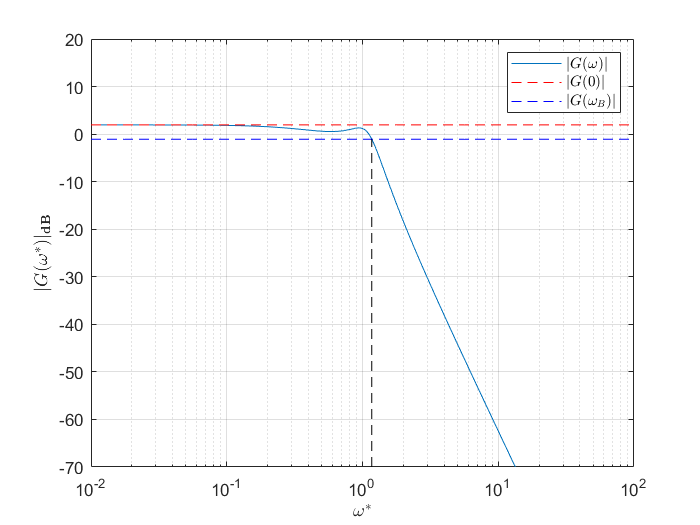

w = 10.^(-2:0.01:2);
J_1 = 0.4; 
J_2 = 1;
B_1 = 0.3;
B_2 = 0.5;
K = 0.3;
kappa_1 = B_1/J_1; 
kappa_2 = B_2/J_2;
beta_1 = K/J_1;
beta_2 = K/J_2;
im = (kappa_1+kappa_2+beta_1*beta_2)*w-w.^3;
re = beta_1*kappa_2+beta_2*kappa_1-(beta_1+beta_2)*w.^2;
mag_G = kappa_1./sqrt(re.^2+im.^2);
pha_G = -atan(im./re);
clf;
ax = axes;
semilogx(ax,w,20*log10(mag_G));
grid(ax,'on');
hold(ax,'on');
DC_gain = kappa_1/(beta_1*kappa_2+beta_2*kappa_1);
semilogx(ax,w,20*log10(DC_gain*ones(size(w))),'r--');
semilogx(ax,w,20*log10(DC_gain/sqrt(2)*ones(size(w))),'b--');
plot(ax,[1.170798 1.170798],[-70 -1.0721],'k--')
axis(ax,[min(w) max(w) -70 20]);
xlabel('$\omega^*$','Interpreter',"latex")
ylabel('$|G(\omega^*)|_\mathbf{dB}$','Interpreter',"latex")
legend({'$|G(\omega)|$','$|G(0)|$','$|G(\omega_B)|$'},'Interpreter',"latex")

เราจะได้ว่า bandwidth ของระบบเครื่องกลนี้อยู่ที่ $1\ldotp 170798\;\left\lbrack \frac{\textrm{rad}}{s}\right\rbrack$ หรือประมาณ $0\ldotp 1863\;\left\lbrack \textrm{Hz}\right\rbrack$

**เราสามารถออกแบบตัวกรองสัญญาณจาก bandwidth ของระบบได้ เนื่องจากระบบจริงมีการตอบสนองในช่วงของ bandwidth เราสามารถกรองสัญญาณรบกวนที่มีความถี่สูงกว่า bandwidth ออกไปได้** ในกรณีตัวอย่าง เราสามารถออกแบบตัวกรอง low-pass ที่มีความถี่ตัดในบริเวณ $0\ldotp 1863\;\left\lbrack \textrm{Hz}\right\rbrack$ 

เราสามารถสรุปกระบวนการประมาณ bandwidth ได้ดังต่อไปนี้

- กราฟแผนภาพโบเดในส่วนของ อัตราส่วนขยาด

- คำนวณหา อัตราส่วนขนาด ณ อินพุตคงที่ ${\left|G\left(0\right)\right|}_{\textrm{dB}}$

- นำอัตราส่วนขนาด(ในเดซิเบล) ไปลบด้วย $10\log_{10} \left(2\right)$ หรือประมาณ $3\;\textrm{dB}$

- วาดเส้นแนวนอนในกราฟที่ค่าผลลบที่หามาได้ 

- ดูจุดตักระหว่างกราฟและเส้นแนวนอน และหาพิกัดของความถี่ ณ จุดตัดนั้น